clf;
%%Testskript für die Blattauslegung mit Betz/Schmitz
%%zum erstellen eines neuen Profils Rotorradius, schnelllaufzahl und
%%Blattanzahl. Danach noch den profilnamen eingeben (z. Zt. gehen nur NACA
%%4-Digit Profile. der Radius bei dem das Profil hinzugefügt werden soll, 
%%Anstellwinkel,  und Postion der Blattachse eingeben. Zum Bearbeiten muss
%%"edit" auf 1 gesetzt sein. Ansonsten werden nur vorhanden Profile
%%geplottet

%%globale Variablen des Rotors
R=50;           %%Rotorradius [m]
lamda_A=7;      %%Schnelllaufzahl   [1]
z=3;            %%Blattanzahl       [1}

%%lokale Variablen zum einfgügen der Profile
name='naca1412';    %%Profilname gerade nur NACA 4-digit profile, z.B. "NACA0012", oder "Cir_2.1" für 2.1m kreis
%%alpha_A=6;          %%Anstellwinkel     [°]
t=0.25;             %%Position Blattachse
r=18;               %%Position des Profils auf dem Blatt

edit=1;             %%edit an oder aus


## load foildatabase

fileName='foils_imported.dat';

foil_db=readtable(fileName)

foil_db = 21×7 table
        foil_name         AoA_eps    CL_eps    CD_eps     AoA_lift    CL_lift    CD_lift
    __________________    _______    ______    _______    ________    _______    _______

    {'NACA 63(4)-221'}       7.5     1.0357    0.00959     19.25      1.3158     0.09175
    {'NACA 63(4)-421'}      7.25     1.1692    0.00982      18.5      1.4023     0.09052
    {'NACA 63-412'   }      4.25     0.8168    0.00706     14.75      1.4179     0.05104
    {'NACA 64A-010'  }         6     0.6692    0.01151        10      0.9479     0.03032
    {'fx66s196'      }       8.5     1.3757    0.01001      9.25      1.4022     0.01109
    {'fx77w270s'     }     11.25     1.6023    0.01575        15      1.8266     0.02568
    {'fx83w160'      }      

## check if foil exists in db

Index =find(strcmp(name,foil_db.foil_name))

Index = 16

## Profile erstellen und anhängen

if edit==1
   if exist('prof')==0
       prof=blade_root(R)
       if r>= 0.15*R
            prof(3)=foil_transform(R,r,name,lamda_A,z, t,foil_db);
       else
            disp('Profil ist zu nah an der Blattwurzel. Anderen Profilposition waehlen!')    
       end       
     else
       if check_existing(prof,r) == 0 & r>= 0.15*R
            l=length(prof);
            prof(l+1)=foil_transform(R,r,name,lamda_A,z, t,foil_db);
            prof=bld_sort(prof);
       else
           disp('Profil an dieser Blattposition existiert bereits oder ist zu nah an der Blattwurzel. Anderen Profilposition waehlen!')
       end
   end
end

existing = logical
   1


Profil an dieser Blattposition existiert bereits oder ist zu nah an der Blattwurzel. Anderen Profilposition waehlen!


## plot der profile

bld_plot(prof)

l = 3

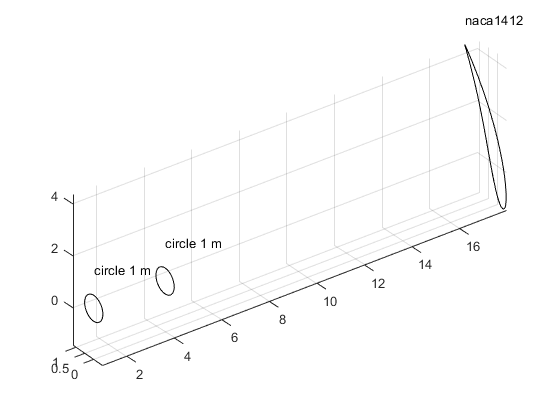

grid on